### Pruebas de una red de tres capas con entrenamiento por Backpropagation

Aquí me gustaría resolver dos problemas que creo han quedado conceptualmente pendientes. Una sería la resolución del problema xOR, el cual habiamos visto que no se podía resolver con una neurona de perceptrón, ya que no se trataba de un problema que fuera linealmente separable. En teoría con nuestra red de tres capas ya debiese ser sencillo resolver dicho problema, así que esto es lo que haré primero: Posteriormente me gustaría intentar aproximar alguna función usando esta red de tres capas, para no restringirnos a funciones armónicas yo creo que haré la prueba con alguna función mas exótica como las de Bessel. 

%Es importante importar nuestros códigos para las funciones de activación
addpath("G:\Mi unidad\MCC\Primer Semestre\Inteligencia artificial\Codigos\Funciones de activacion");

#### Problema xOR

Para este problema usaremos la función de activación sigmoide en ambas capas. Si recordamos la ecuación de dicha función es de la siguiente forma:


$$f(x) = \frac{1}{1 + e^{-x}}$$


La derivada de dicha función sería la siguiente:

l$\frac{d/(1+e^{-x})^{-1}}{dx} = (-1)(1+e^{-x})^{-2}(-1)e^{-x}  =\frac{e^{-x}}{(1+e^{-x})^2} = \left(\frac{1}{1+e^{-x}}\right)\left( 1-\frac{1}{1+e^{-x}}\right) = f(x)(1-f(x))$

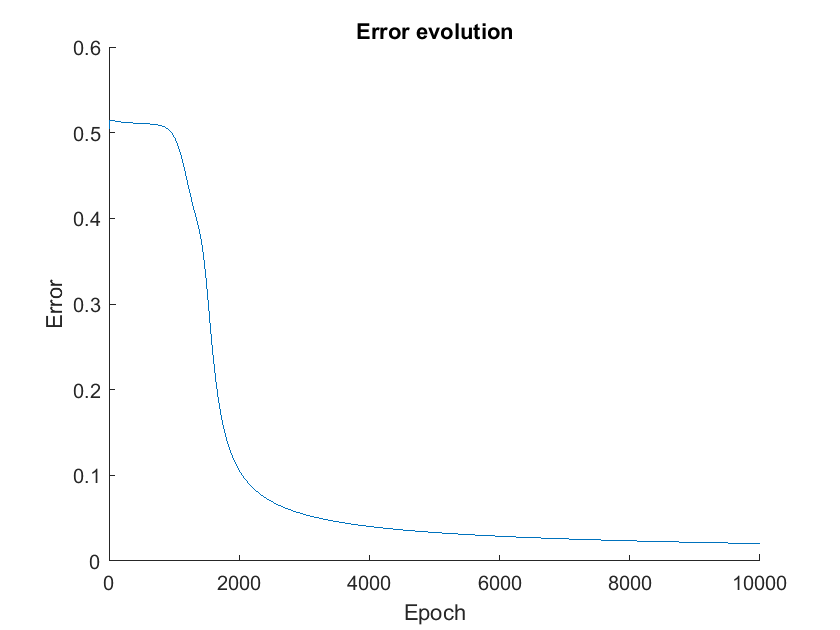

%Definimos nuestra red de tres capas, aquí se tienen dos entradas y una
%salida, así que haré que tengamos digamos dos neuronas en la capa
%intermedia y una en la de salida. 
firstLayerNeurons = 2;
firstLayerInputs = 2;
outputs = 1;
der1 = @(x) (1-x)*x;
der2 = @(x) (1-x)*x;
activation1 = LogSigmoid();
activation2 = LogSigmoid();
%Creamos la red 
network = ThreeLayerNetwork(firstLayerNeurons,firstLayerInputs,outputs,activation1,activation2,der1,der2);
%Nuestras entradas para el entrenamiento 
inputs = [0 0 1 1; 0 1 0 1];
targets = [0 1 1 0];
%Realizamos el entrenamiento de nuestra red
alpha = 0.2;
epochs = 10000;
[network, errors] = network.train(inputs,targets,alpha,epochs);
epochInterval = 1:1:epochs;
figure()
hold on 
title("Error evolution")
plot(epochInterval,errors)
xlabel("Epoch")
ylabel("Error")
hold off

Vamos a obtener la tabla de verdad que resulta a partir de la red entrenada.

% Tabla resultante de la función xOR
firstEntry = inputs(1,:)';
secondEntry = inputs(2,:)';
outputExtract = @(x) x{2};
results = arrayfun(@(x,y)outputExtract(network.compute([x;y])),firstEntry,secondEntry);
T = table(firstEntry,secondEntry,results,'VariableNames',{'x','y','x xOR y'})

T = 4×3 table
    x    y    x xOR y 
    _    _    ________

    0    0    0.020624
    0    1     0.97799
    1    0      0.9778
    1    1    0.027565


Muy bien, ahora me gustaría hacer la visualización de como se están separando los puntos, para esta parte como se están ocupando dos neuronas, tenemos dos lineas para separar. 

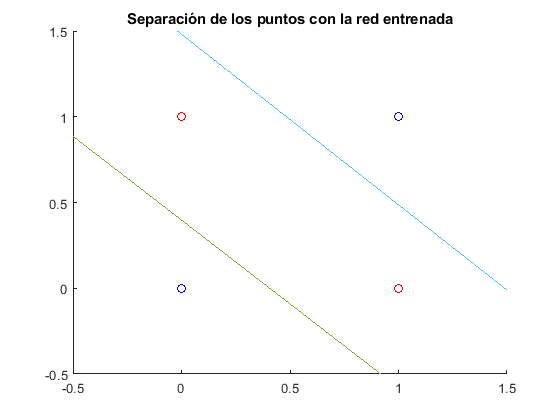

x = linspace(-0.5,1.5,1000);
y1 = -network.b1(1)/network.W1(1,2) - (network.W1(1,1)/network.W1(1,2))*x;
y2 = -network.b1(2)/network.W1(2,2) - (network.W1(2,1)/network.W1(2,2))*x;
figure()
hold on 
title("Separación de los puntos con la red entrenada")
for i = 1:length(targets)
    point = inputs(:,i);
    if(targets(i) == 0)
        plot(point(1),point(2),'o','color','blue')
    else
        plot(point(1),point(2),'o','color','red')
    end
end
%First line
plot(x,y1)
%Second line
plot(x,y2)
xlim([-0.5,1.5])
ylim([-0.5,1.5])
hold off

### Aproximación de una función bessel 

Para este caso las funciones de activación a utilizar son sigmoidal en la capa interna, y lineal en la capa final. 

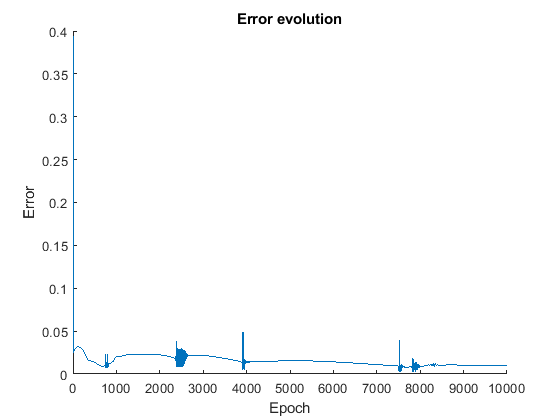

xInt = linspace(0,10,100);
yInt = besselj(0,xInt);
numberOfNeurons = 15;
inputNumber = 1;
outputs = 1;
activation1 = LogSigmoid();
activation2  = Linear();
der1 = @(x) x*(1-x);
der2 = @(x) 1;

besselNetwork = ThreeLayerNetwork(numberOfNeurons,inputNumber,outputs,activation1,activation2,der1,der2);
epochs = 10000;
alpha = 0.1;
[besselNetwork, errors] = besselNetwork.train(xInt,yInt,alpha,epochs);
epochInterval = 1:1:epochs;

figure()
hold on 
title("Error evolution")
plot(epochInterval,errors)
xlabel("Epoch")
ylabel("Error")
hold off

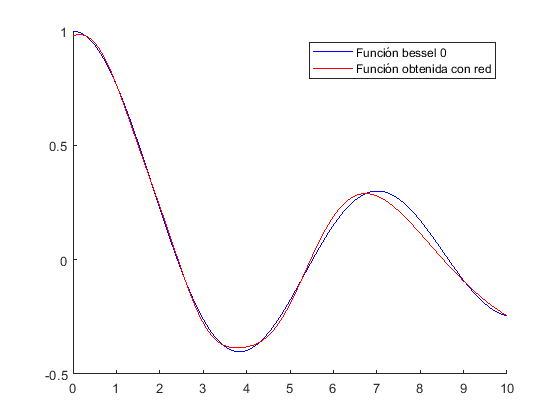

outputExtract = @(x) x{2};
yNet = arrayfun(@(x) outputExtract(besselNetwork.compute(x)),xInt);

figure()
hold on 
plot(xInt,yInt,'color','blue')
plot(xInt,yNet,'color','red')
legend('Función bessel 0','Función obtenida con red')
hold off

## Red predictiva de fuerza invariante del tiempo a partir de ejemplos de movimiento cuando dicha fuerza está actuando. 

La segunda ley de Newton nos dice que todas las fuerzas de la naturaleza, independientemente de la naturaleza de las mismas (las constantes de las que dependan, o dependencias espacio-temporales) influyen de la misma forma en los objetos: acelerandolos en proporción a su masa. Objetos mas pesados tienen mayor inercia y es mas dificil modificar su velocidad. 

Para un movimiento en dos dimensiones se tiene lo siguiente:


$$\vec{F} = m \frac{d^2\vec{r}}{dt^2} = \left(m\frac{d^2x}{dt^2},m\frac{d^2 y}{dt^2}\right)$$


Lo que intentaremos hacer es entrenar a una red para que arroje la fuerza en dependencia de la posición a partir de ejemplos de movimiento de una partícula. 

El ejemplo particular que escogeremos es el de un resorte que oscila, donde sabemos que la fuerza viene dada por una ecuación constitutiva conocida como ley de hooke:


$$\vec{F} = -kx$$


Notese que la fuerza en este caso no depende del tiempo, en esto baso mi suposición de que probablemente podamos usar nuestra red como la hemos construido, y que no necesitariamos examinar evolución temporal usando por ejemplo redes de recurrencia. 

Como no tengo datos experimientales del movimiento de un resorte voy a simular algunas series de tiempo usando la ecuación de movimiento que corresponde a dicha fuerza:


$$m\ddot{x} +kx = 0$$


La solución de está ecuación diferencial son funciones armónicas de forma:


$$x(t) = A\cos\left(\sqrt{\frac{k}{m} }t + \phi\right)$$


Donde A es la amplitud de la oscilación y $\phi$ es un desfase. Estas constantes dependen unicamente de las condiciones iniciales$x(0)$ y $\dot{x}(0)$.

La aceleración la estaremos obteniendo numericamente porque precisamente la idea sería poder obtener información de la naturaleza de la fuerza a partir de datos crudos de movimiento de algún objeto.(datos de posición respecto al tiempo). 

%Masas que usaremos para generar los datos 
masses = linspace(0.1,1,5);
%Vamos a generar varias series de tiempo con estas masas todas a varias
%velocidades, en todas ellas usaremos una posición inicial de 0 y una
%velocidad inicial de 10 
initialPos = 0;
initialVel = 3;
%Las fases y amplitud que corresponden a las condiciones iniciales. 
k = 0.5;
phase = pi/2;
amplitudes = initialVel*sqrt(masses/k);

xData = [];
fData = [];
tArray = linspace(0,20,1000);
deltaT = diff(tArray);
deltaT2 = deltaT(2:end);
for i = 1:length(masses)
    mass = masses(i);
    amplitude = amplitudes(i);
    xTimeSeries = amplitude*cos(sqrt(k/mass)*tArray - phase);
    velocity = diff(xTimeSeries)./deltaT; 
    acceleration = diff(velocity)./deltaT2;
    %Calculamos la fuerza a prtir de series de tiempo como masa*
    %aceleración
    force = mass*acceleration;
    
    xData = [xData,xTimeSeries(3:end)];
    fData = [fData,force];
end
[xData,sortI] =  sort(xData);
fData = fData(sortI);

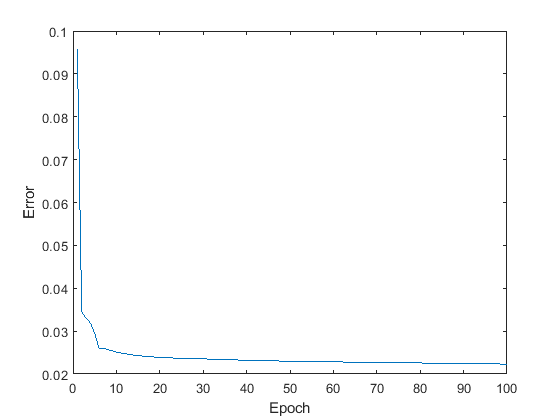

%Ya que tenemos nuestros datos ha llegado el momento de construir nuestra
%red, en este caso vamos a tener 1 entrada, y haremos que la primera capa
%tenga digamos  neuronas, la salida también esta confomrmada por un solo
%número que corresponde a la fuerza para una posición dada.
flNeurons = 15;
nInputs = 1;
outputs = 1;
activation1 = LogSigmoid();
activation2  = Linear();
der1 = @(x) x*(1-x);
der2 = @(x) 1;
alpha = 0.2;
epochs = 100;
hookeNetwork = ThreeLayerNetwork(flNeurons,nInputs,outputs,activation1, activation2,der1,der2);

%Entrenamos nuestra red
[hookeNetwork,errors] = hookeNetwork.train(xData, fData,alpha,epochs);
epochInterval = 1:1:epochs;
figure()
title("Evolución del error")
plot(epochInterval, errors)
xlabel("Epoch")
ylabel("Error")

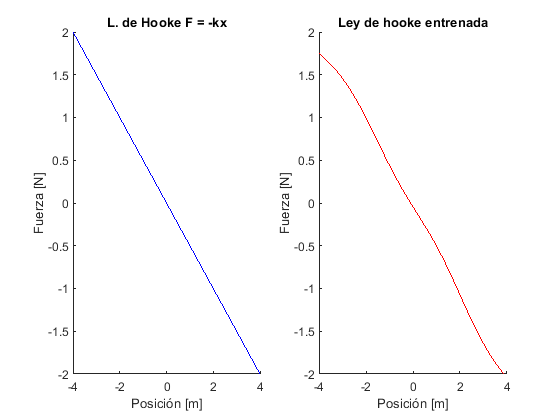

xInterval = linspace(-4,4,100);
yInterval = -k*xInterval;
outputExtract = @(x) x{2};
yNet = arrayfun(@(x)outputExtract(hookeNetwork.compute(x)),xInterval);
subplot(1,2,1)
hold on 
title("L. de Hooke F = -kx")
plot(xInterval,yInterval,'color','blue')
xlabel("Posición [m]")
ylabel("Fuerza [N]")
ylim([-2,2])
hold off
subplot(1,2,2)
hold on 
title("Ley de hooke entrenada")
plot(xInterval, yNet,'color','red')
xlabel("Posición [m]")
ylabel("Fuerza [N]")
ylim([-2,2])
hold off

### Prueba backpropagation con momento

Otra de las cosas que implementé, fue el método de backpropagation con momento, esto porque en un principio no convergia la red y pensé que la razón era que se estaba deteniendo en un punto local. A final de cuentas se debía a un error en el código sin embargo la implementación quedó, así que valdria la pena presentarlo brevemente, lo que haremos será hacer el entrenamiento de Bessel con ella, lo haremos con menos iteraciones, para ver que sucede.

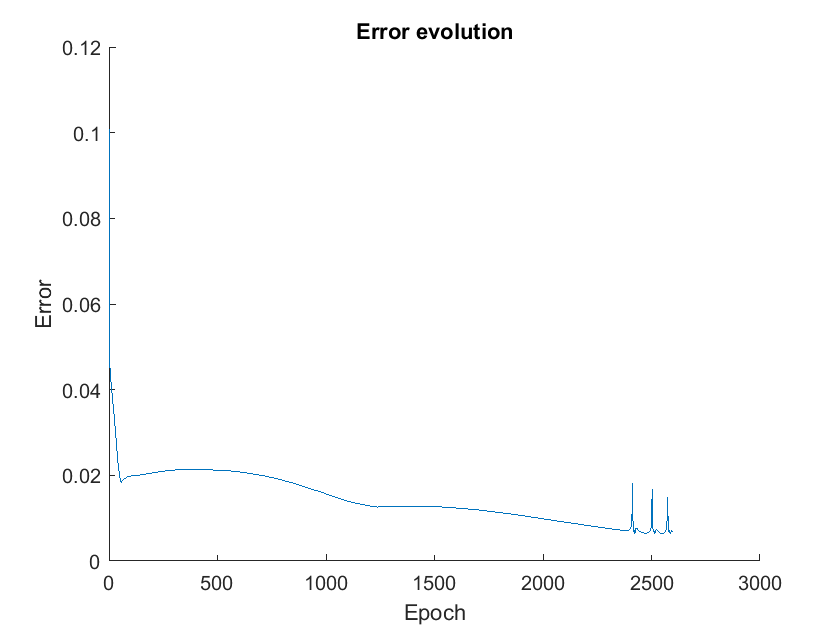

xInt = linspace(0,10,100);
yInt = besselj(0,xInt);
numberOfNeurons = 15;
inputNumber = 1;
outputs = 1;
activation1 = LogSigmoid();
activation2  = Linear();
der1 = @(x) x*(1-x);
der2 = @(x) 1;

besselNetwork = ThreeLayerNetwork(numberOfNeurons,inputNumber,outputs,activation1,activation2,der1,der2);
epochs = 2600;
alpha = 0.05;
gamma = 0.007;
[besselNetwork, errors] = besselNetwork.trainWithMomentum(xInt,yInt,alpha,gamma,epochs);
epochInterval = 1:1:epochs;

figure()
hold on 
title("Error evolution")
plot(epochInterval,errors)
xlabel("Epoch")
ylabel("Error")
hold off

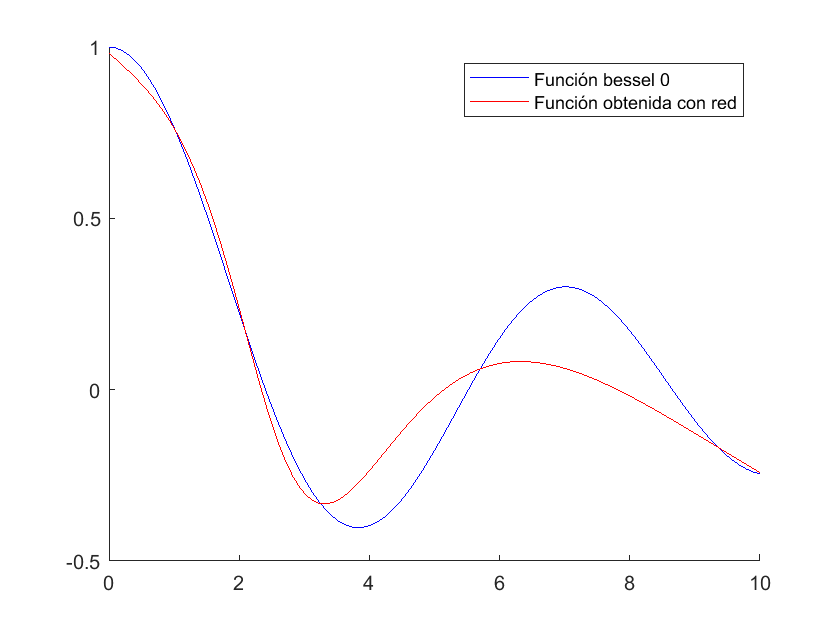

outputExtract = @(x) x{2};
yNet = arrayfun(@(x) outputExtract(besselNetwork.compute(x)),xInt);

figure()
hold on 
plot(xInt,yInt,'color','blue')
plot(xInt,yNet,'color','red')
legend('Función bessel 0','Función obtenida con red')
hold off

La aproximación no es perfecta, me parece que faltaría ajustar bien el factor de aprendizaje y gamma para este caso. 